# Plot the zeroth order Poynting vector in Fourier space of the SFG scattered field for a sweep of parameters

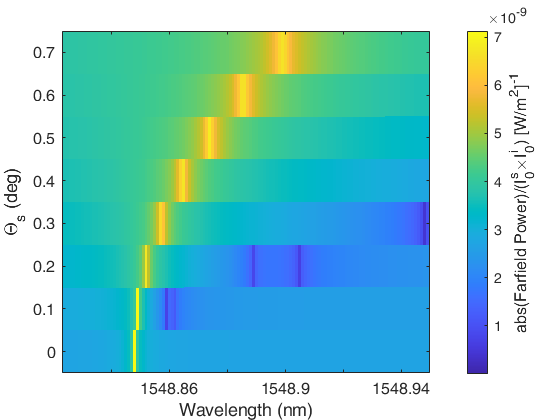

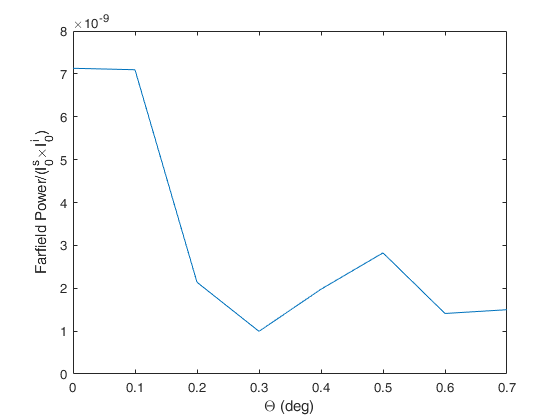

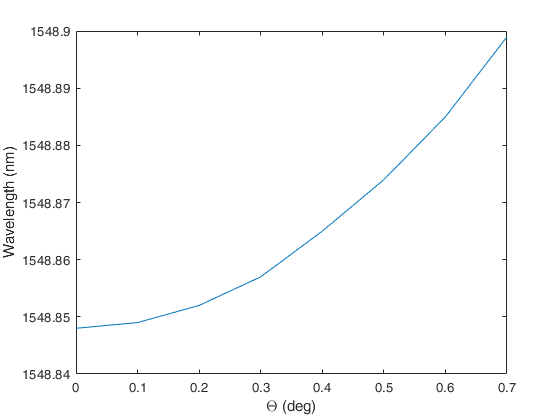

clear;
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL');
addpath(genpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\analysis'));
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config');
addpath(genpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed'));


max_enhancement = 1e-20;
min_enhancement = 1;

fft_zeroth = [];
fft_yvals = [];
fft_max = [];
fft_max_lda = [];
max_index = [];

for job = "cylinder_dimer_no_substrate_111_6"

    eval(job);
    extra_options = matthew_extra_options(options);
    load([options.output_dir_final 'sweep_data.mat']);
    
    for study_num = 1:height(sweep_data)
        derived_values = sweep_data(study_num,:).DerivedValues{1};
        sum_fft = sweep_data(study_num,:).SumFFT{1};
        
        denom = derived_values.parameters.I0*derived_values.parameters.I0_i;
            
        wlengths = 299792458./derived_values.signal.freq;
        
        for cut_plane_index = 1:length(extra_options.cut_plane)
            for direction = extra_options.direction
                
                [FTx, FTy, FTz,FThx, FThy, FThz, FTpoynting] = ...
                    matthew_get_fft_of_cut_plane_all_freqs(sum_fft, ...
                    extra_options.cut_plane(cut_plane_index), direction);
                
                for FT_num = 5%1:5
                    switch FT_num
                        case 1
                            FTxyz = FTx;
                            FThxyz = FThx;
                        case 2
                            FTxyz = FTy;
                            FThxyz = FThy;
                        case 3
                            FTxyz = FTz;
                            FThxyz = FThz;
                        case 4
                            FTxyz = abs(FTx).^2 + abs(FTy).^2;
                            FThxyz = abs(FThx).^2 + abs(FThy).^2;
                        otherwise
                            FTxyz = FTpoynting;
                    end
                    
                    if max(abs(FTxyz(:,2,2))/denom) > max_enhancement
                        max_enhancement = max(abs(FTxyz(:,2,2))/denom);
                    end
                    if min(abs(FTxyz(:,2,2))/denom) < min_enhancement
                        min_enhancement = min(abs(FTxyz(:,2,2))/denom);
                    end
                    
                    fft_zeroth = [fft_zeroth; (abs(FTxyz(:,2,2))/denom)'];
                    fft_yvals = [fft_yvals str2num(erase(sweep_data(study_num,:).theta, "[deg]"))];
                    fft_max = [fft_max max(abs(FTxyz(:,2,2))/denom)];
                    [~,i]=max(abs(FTxyz(:,2,2))/denom);
                    fft_max_lda = [fft_max_lda wlengths(i)];
                    max_index = [max_index i];
                    
                end
            end
        end
    end
    
    fig = figure;
    imagesc(wlengths, fft_yvals, fft_zeroth);
    axis([wlengths(end) 1548.95 -0.05 0.75]);
    view(0,-90);
    ylabel("\Theta_s (deg)", 'FontSize', 14);
    xlabel("Wavelength (nm)", 'FontSize', 12);
    set(gca, 'Ytick', fft_yvals);
    cb = colorbar;
    caxis([min_enhancement max_enhancement]);
    ylabel(cb, "abs(Farfield Power)/(I_0^s\timesI_0^i) [W/m^2]^{-1}", 'FontSize', 12)
    set(gca,'ColorScale','log');
    axis([wlengths(end) 1548.95 -0.05 0.75]);
    %title(job, 'Interpreter', 'none');
    saveas(fig, strcat("C:\Users\Matthew\Downloads\",job, "_fft_all"), 'png');

    figure;
    plot(fft_yvals, fft_max);
    ylabel("Farfield Power/(I_0^s\timesI_0^i)")
    xlabel("\Theta (deg)");
    
    figure;
    plot(fft_yvals, fft_max_lda);
    ylabel("Wavelength (nm)")
    xlabel("\Theta (deg)");
end